clear
clf

Recall that $y=A\;\mathrm{sin}\left(2\pi \;f\;x\;+\;\phi \right)=A\;\mathrm{sin}\left(\omega \;x\;+\;\phi \right)$,

where   $A=\mathrm{amplitude}$

            
$$f=\mathrm{frequency}\;\left(\mathrm{cycles}\;\mathrm{per}\;___\right)$$


            $\omega =\textrm{angular}\;\textrm{frequency}\;\left(\mathrm{radians}\;\textrm{per}\;___\right)$     [$\omega =2\pi \;f$]

            
$$\phi =\mathrm{phase}\;\mathrm{offset}\;\left(\mathrm{radians}\right)$$


First, we'll generate a "continuous" sine wave (see note below). Play with the parameters if you aren't clear on how they affect the shape of the sine wave function.

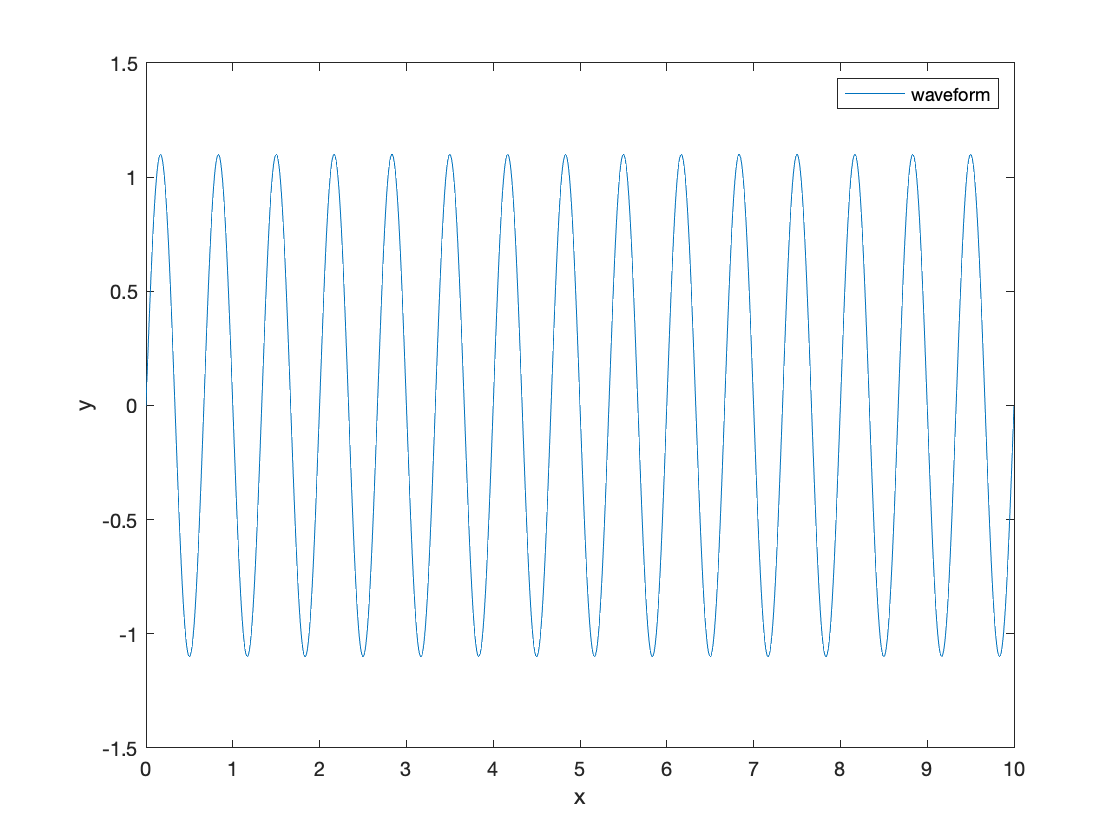

%Set underlying sine function parameters
A = 1.1; %amplitude
f = 1.5; %frequency
phi = 0; %phase

%Generate a "continuous" dataset
dx = 0.01;
x = 0:dx:10;
y = A.*sin(2.*pi.*f.*x + phi);

%Plot the "continuous" data
figure(1)
plot(x,y)
xlabel('x')
ylabel('y')
legend('waveform')

Obviously this is not really a continuous dataset, since we're generating it at discrete values of x. However, we're choosing a very small sample rate here (0.01), so at least as far as the figure is concerned, this will look continuous (think about why this is, in terms of sampling rate and frequency $f$ once you finish this exercise).

Now we'll look at the same function sampled at a lower rate, at which we can actually see the effects of discrete sampling.

Choose a sample frequency (start with one less than the waveform frequency you set above).

%Sample frequency
fs =4.15;


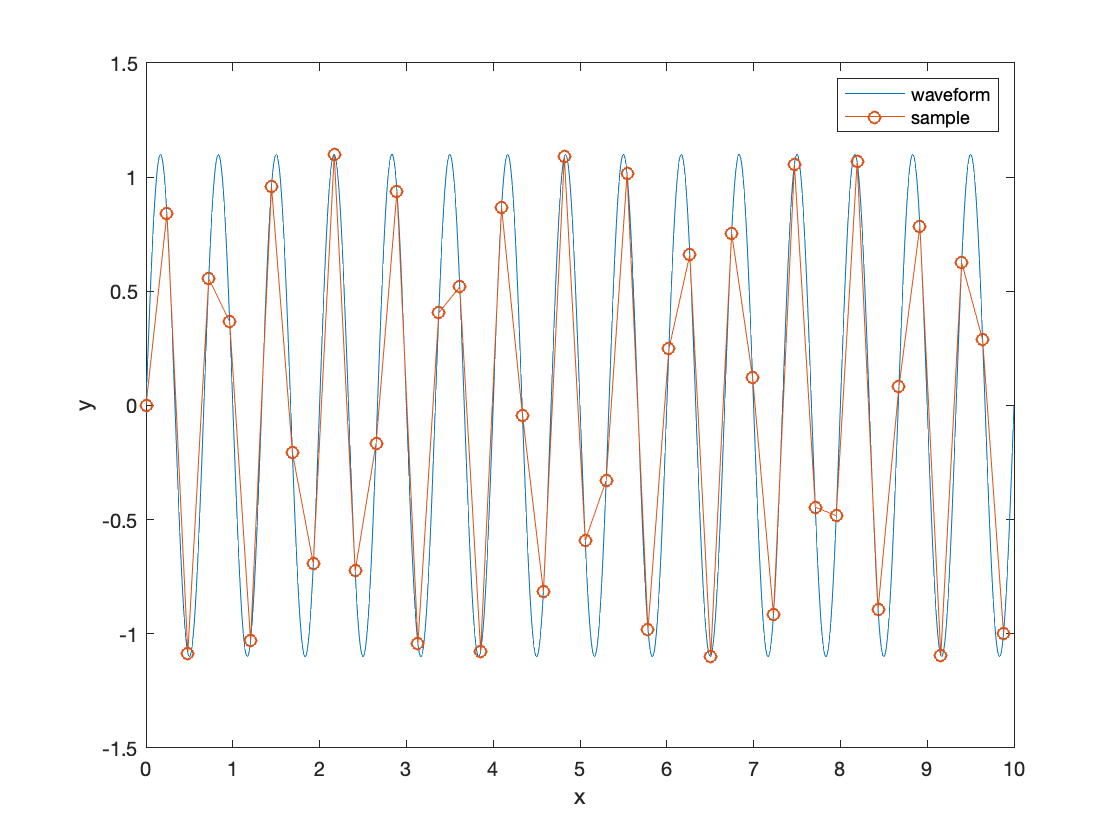

%Generate a sample dataset at discrete values sampled at 1/fs
dxs = 1/fs;

xs = 0:dxs:10; %sample x-values
ys = A.*sin(2.*pi.*f.*xs+ phi); %sample y-values

%Plot original sine wave along with discrete sample values and inferred waveform
plot(x,y,xs,ys,'-o')
xlabel('x')
ylabel('y')
legend('waveform','sample')

Finally, we'll plot a power spectrum for both the original waveform and the discretely sampled signal.

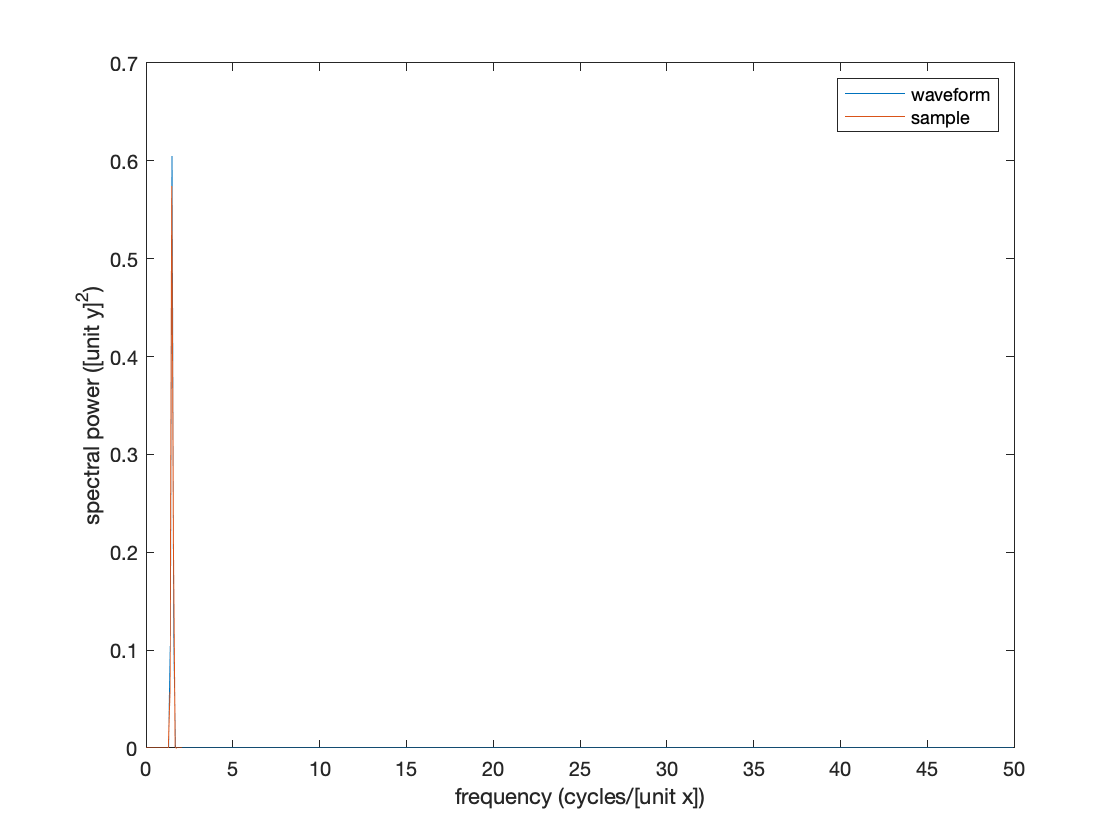

%Calculate power spectrum for original signal
window = hamming(length(y)); %create hamming window to taper signal and avoid edge artifacts
nfft = length(y); %number of samples to use for DFT
[P,f_array] = periodogram(y,window,nfft,1/dx,'power');

%Calculate power spectrum for discrete samples
windows = hamming(length(ys)); 
nffts = length(ys); 
[Ps,fs_array] = periodogram(ys,windows,nffts,fs,'power');


% [pwrest,idx] = max(P);
% fprintf('The maximum power occurs at %3.1f Hz\n',f(idx))
% 
% fprintf('The power estimate is %2.2f\',pwrest)
plot(f_array,P,fs_array,Ps);
% xlim([0 10]);
xlabel('frequency (cycles/[unit x])')
ylabel('spectral power ([unit y]^2)')
legend('waveform','sample')

*The Nyquist (or Nyquist-Shannon) Sampling Theorem states that a bandlimited continuous signal can be sampled discretely and reconstructed with perfect fidelity if the waveform is sampled over twice as fast as it's highest frequency component.*

### **Go back and play with the sampling frequency** relative to the function's frequency to get a sense of how undersampling can lead to *aliasing* (misidentification of frequencies), and why the limits below defined by the sampling theorem make sense:

•**Nyquist limit** ( $f_{\mathrm{max}} <f_s /2\;$): the highest frequency component that can be accurately represented with a sampling frequency of ${\;f}_s \;$

•**Nyquist frequency** ($\;{\;f}_N >2{\;f}_{\mathrm{max}} \;$): the minimum sampling rate required to accurately represent frequencies up to ${\;f}_{\max } \;$

*Suggestion: start with a function frequency of *$f=1\ldotp 5\;$* and sample frequency *${\;f}_s \;=0\ldotp 7$*, then slowly increase your sample frequency up to and past *$f$.